load('D:\ppg signal\dataset_BCIcomp1.mat')  %%load data from mat file


C1 = squeeze(x_train(:,1,1:100)); %% separate all 1st columns and squeeze dimension to two
C2 = squeeze(x_train(:,2,1:100)); %% separate all 2nd columns and squeeze dimension to two
C3 = squeeze(x_train(:,3,1:100)); %% separate all 3rd columns and squeeze dimension to two
C4 = y_train(1:100,1); %% results
C1m = mean(C1)'; %% means of all colums and transpose
C2m = mean(C2)'; %% means of all colums and transpose
C3m = mean(C3)'; %% means of all colums and transpose
input_data = [C1m C2m C3m]; %% matrix of all input sensors
data = [C1m C2m C3m C4];  %% combine matrix with input data and results
T_train=array2table(data); %% converting matrix to table
T_train.Properties.VariableNames={'C1','C2','C3','Y'} %%labelling of table columns

T_train = 100×4 table
        C1             C2             C3         Y
    ___________    ___________    ___________    _

     -0.0010957    -0.00080702     -0.0013657    1
     -0.0036074     -0.0043271     -0.0032917    2
      0.0012682     0.00093502     6.1035e-05    2
      0.0014788    -0.00020091     0.00064087    2
     -0.0015127     -0.0029072     -0.0014064    2
     -0.0025842      0.0006574     -0.0011262    1
      -0.001692     -0.0041271     -0.0019095    1
      0.0016085      0.0013525      -4.62e-05    2
    -3.2213e-05     0.00062264      0.0023816    2
    -0.00018989     -0.0013754    -0.00045395    1
     0.00095707    -0.00010045      0.0022918    1
      0.0011088     0.00063833      0.0019654    2
     -0.0014631      0.0015772     0.00028102    1
    -0.00057136     -0.0010707    -0.00092231    2
     -0.0010656      -0.0


C1_test = squeeze(x_train(:,1,101:140)); %% separate all 1st columns and squeeze dimension to two
C2_test = squeeze(x_train(:,2,101:140)); %% separate all 2nd columns and squeeze dimension to two
C3_test = squeeze(x_train(:,3,101:140)); %% separate all 3rd columns and squeeze dimension to two
C4_test = y_train(101:140,1); %% results
C1m_test = mean(C1_test)'; %% means of all colums and transpose
C2m_test = mean(C2_test)'; %% means of all colums and transpose
C3m_test = mean(C3_test)'; %% means of all colums and transpose
input_data_test = [C1m_test C2m_test C3m_test]; %% matrix of all input sensors
data_test = [C1m_test C2m_test C3m_test C4_test];  %% combine matrix with input data and results
T_test=array2table(data_test); %% converting matrix to table
T_test.Properties.VariableNames={'C1','C2','C3','Y'} %%labelling of table columns

T_test = 40×4 table
        C1             C2             C3         Y
    ___________    ___________    ___________    _

      0.0011609       0.001116      0.0029034    2
     0.00075573      0.0028784      0.0012847    2
      0.0022435     0.00013267      0.0017518    2
     0.00090069      0.0017433      0.0017976    1
    -0.00053872      0.0017162     0.00071123    2
      0.0005722    -0.00035138    -0.00065486    2
     0.00028822      0.0013712     0.00058238    2
      0.0005171      0.0020561      0.0018077    1
      0.0034201      0.0040063      0.0021782    1
     -0.0017988     0.00069512    -8.8586e-05    2
     0.00014199      -0.003927     -0.0016017    2
      -0.000924     -0.0020281     0.00065825    2
    -0.00093206      0.0021655    -1.1868e-05    1
    -0.00048998     0.00052643     -0.0015428    1
    -0.00030221     -0.0014


%% Applying KNN 

knnmodel = fitcknn(T_train,"Y","NumNeighbors",5)  %% knn model with 5 neighbours

knnmodel =   ClassificationKNN
           PredictorNames: {'C1'  'C2'  'C3'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 100
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


mdl_loss = loss(knnmodel,T_test)

mdl_loss = 0.3750

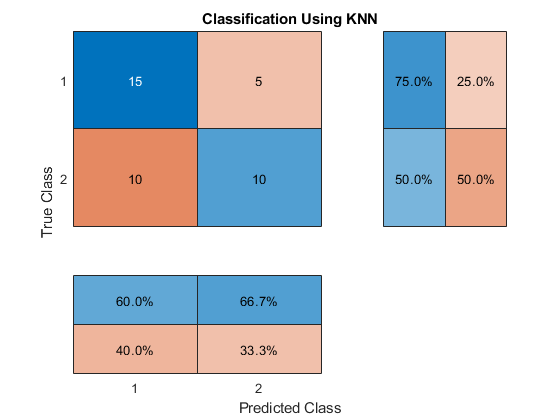

predic = predict(knnmodel,T_test);
conmat = confusionchart(T_test.Y,predic,'RowSummary','row-normalized','ColumnSummary','column-normalized');
conmat.Title = 'Classification Using KNN';

miss = predic ~= T_test.Y;  %% finding missclassification
sum_miss = sum(miss)  %% total miss class

sum_miss = 15


%% applying Naive Bayes

NBmodel = fitcnb(T_train,"Y")  %% Naive model

NBmodel =   ClassificationNaiveBayes
            PredictorNames: {'C1'  'C2'  'C3'}
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: [1 2]
            ScoreTransform: 'none'
           NumObservations: 100
         DistributionNames: {'normal'  'normal'  'normal'}
    DistributionParameters: {2×3 cell}


  Properties, Methods


mdl_loss = loss(NBmodel,T_test)

mdl_loss = 0.4750


%% Applying Decicion tree

DTmodel = fitctree(T_train,"Y")  %% Decision Tree model

DTmodel =   ClassificationTree
           PredictorNames: {'C1'  'C2'  'C3'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 100


  Properties, Methods


mdl_loss = loss(DTmodel,T_test)

mdl_loss = 0.5250


%% applying SVM

SVMmodel = fitcsvm(T_train,"Y")  %%SVM

SVMmodel =   ClassificationSVM
           PredictorNames: {'C1'  'C2'  'C3'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 100
                    Alpha: [100×1 double]
                     Bias: -2.8290e-04
         KernelParameters: [1×1 struct]
           BoxConstraints: [100×1 double]
          ConvergenceInfo: [1×1 struct]
          IsSupportVector: [100×1 logical]
                   Solver: 'SMO'


  Properties, Methods


mdl_loss = loss(SVMmodel,T_test)

mdl_loss = 0.4750